%

# **信道衰落模拟**

自由空间中，信号没有散射、折射、反射等导致能量损失的情况。因此在通信系统中得到系统的损耗表达式为：


$$ L_f = \frac{P_t}{P_r}=(\frac{4\pi d}{\lambda})^2G_rG_t\\$$


%-----------Parameters Setting------------
LightSpeedC=3e8;
BlueTooth=2400*1000000;%hz    
Zigbee=915.0e6;%hz    
Freq=BlueTooth;
TXAntennaGain=0.5;%db
RXAntennaGain=1;%db
PTx=0.001;%watt
sigma=6;%Sigma from 6 to 12 %Principles of communication systems simulation with wireless application P.548
mean=0;
PathLossExponent=2;%Line Of sight

%------------ FRIIS Equation --------------
% Friis free space propagation model:
%        Pt * Gt * Gr * (Wavelength^2)
%  Pr = --------------------------
%        (4 *pi * d)^2 * L

pr_set = [];
for Dref = 0:1:1000
    Wavelength=LightSpeedC/Freq;
    PTxdBm=10*log10(PTx*1000);
    M = Wavelength / (4 * pi * Dref);
    Pr0= PTxdBm + TXAntennaGain + RXAntennaGain - (20*log10(1/M));
    pr_set = [pr_set, Pr0];
end

Wavelength=LightSpeedC/Freq

Wavelength =    0.125000000000000


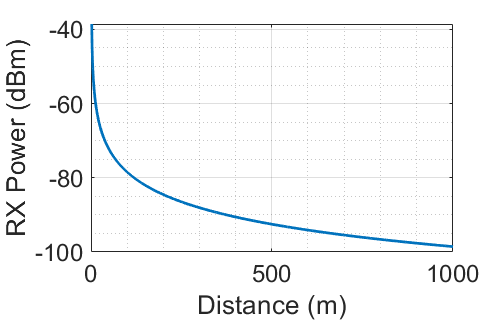


figure;
fg = plot(pr_set);
set(fg,'Linewidth',2);
ylabel('RX Power (dBm)');
xlabel('Distance (m)');
grid on;
set(gca, 'XMinorGrid','on');
set(gca, 'YMinorGrid','on');

set(gcf, 'position', [600 500 500 320]);
set(gca, 'FontSize', 18, 'FontName', 'Arial', 'FontWeight', 'normal');

发射功率对模型结果的影响

%-----------Parameters Setting------------
LightSpeedC=3e8;
BlueTooth=2400*1000000;%hz    
Zigbee=915.0e6;%hz    
Freq=BlueTooth;
TXAntennaGain=0.5;%db
RXAntennaGain=1;%db
PTx=0.001;%watt
sigma=6;%Sigma from 6 to 12 %Principles of communication systems simulation with wireless application P.548
mean=0;
PathLossExponent=2;%Line Of sight

%------------ FRIIS Equation --------------
% Friis free space propagation model:
%        Pt * Gt * Gr * (Wavelength^2)
%  Pr = --------------------------
%        (4 *pi * d)^2 * L

pr_set = [];
for Dref = 0:1:1000
    Wavelength=LightSpeedC/Freq;
    PTxdBm=10*log10(PTx*1000);
    M = Wavelength / (4 * pi * Dref);
    Pr0= PTxdBm + TXAntennaGain + RXAntennaGain - (20*log10(1/M));
    pr_set = [pr_set, Pr0];
end

# 衰落叠加综合

综合看传播路径衰落（Path Loss）、遮挡（Shadowing）、多径（Narrowband Fading）对接收信号的影响（如下图）。Path Loss造成信号衰减是均匀的、单调的；Shadowing造成的衰减相对更快（比Path Loss），断崖下跌；Fading造成的衰减是快速变化的（由于频率高），基本呈现零均值高斯分布。